# Surface Mesh Processing

% The script computes the mean and Gaussian curvature via the local quadaratic surface parameterization. 
% The brief explenation is gven in [1]. The mathematical detail is given in [2].
%
% Chung, M.K., Worsley, K.J., Robbins, S., Evans, A.C. 2003. 
% Tensor-based brain surface modeling and analysis, CVPR, 467-473
% http://pages.stat.wisc.edu/~mchung/papers/CVPR/CVPR.pdf
%
% Chung. M.K. 2001, Statistical Morphometry in Computional Neuroanatomy, 
% PhD Thesis, McGill University, Montreal. 
% http://www.stat.wisc.edu/~mchung/papers/thesis.pdf
%
% The code below is used in performing the mesh processing done in
%
% Huang, S.-G., Lyu, I., Qiu, A., Chung, M.K. 2020. 
% Fast polynomial approximation of heat kernel convolution on manifolds and 
% its application to brain sulcal and gyral graph pattern analysis, 
% IEEE Transactions on Medical Imaging 39:2201-2212
% http://pages.stat.wisc.edu/~mchung/papers/huang.2020.TMI.pdf
% In the paper, we concluded that year 2003 method ias as competative as year 2020 technique. 
%
%
%% (C) 2021 Moo K. Chung
% Univesity of Wisconsin-Madison
%
% Update history:
%
% Created 2019 August 23
% Commented 2021 November 24
% Updated 2023 July 11


## Load amygdala surface data

%The amygdala surface data is published in 

%Chung, M.K., Worsley, K.J., Nacewicz, B.M., Dalton, K.M., Davidson, R.J. 2010. 
%General multivariate linear modeling of surface shapes using SurfStat. NeuroImage. 53:491-505
% http://pages.stat.wisc.edu/~mchung/papers/chung.2010.NI.pdf

% chung.2010.NI.mat file contains information about age, brain volume,
% The details and additional codes on the data is given in http://pages.stat.wisc.edu/~mchung/research/amygdala/

% For exmple here, we will only use the left amygdala surface for the first subject. 
load 'chung.2010.NI.mat';
surf.vertices=squeeze(left_surf(1,:,:));
surf.faces=sphere.faces;

## Normal vector at face

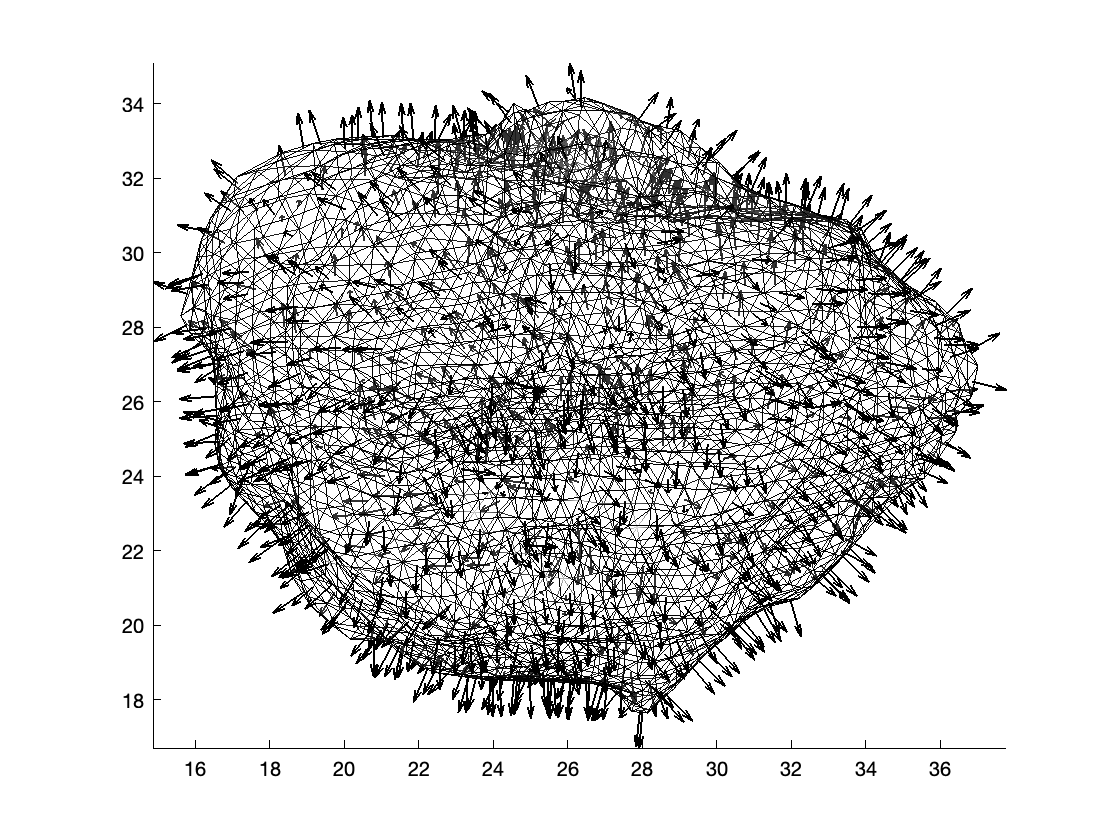

% The unit normal vector of triangle face can be either outward or inward.
% The unit normal vector is computed based on which triangle vertex comes first
% in surf.faces. Need to make sure that the unit normal vectors are all outward. 

load 'chung.2010.NI.mat';
surf.vertices=squeeze(left_surf(1,:,:));
surf.faces=sphere.faces;

%Computer the normal vectors at faces
normals = faceNormal(surf);
%Computer the centers of faces
center = faceCenter(surf);

figure; figure_wire(surf,'k', 'w');
hold on; figure_quiver3D(center, normals, 5);

## Normal vector at vertex

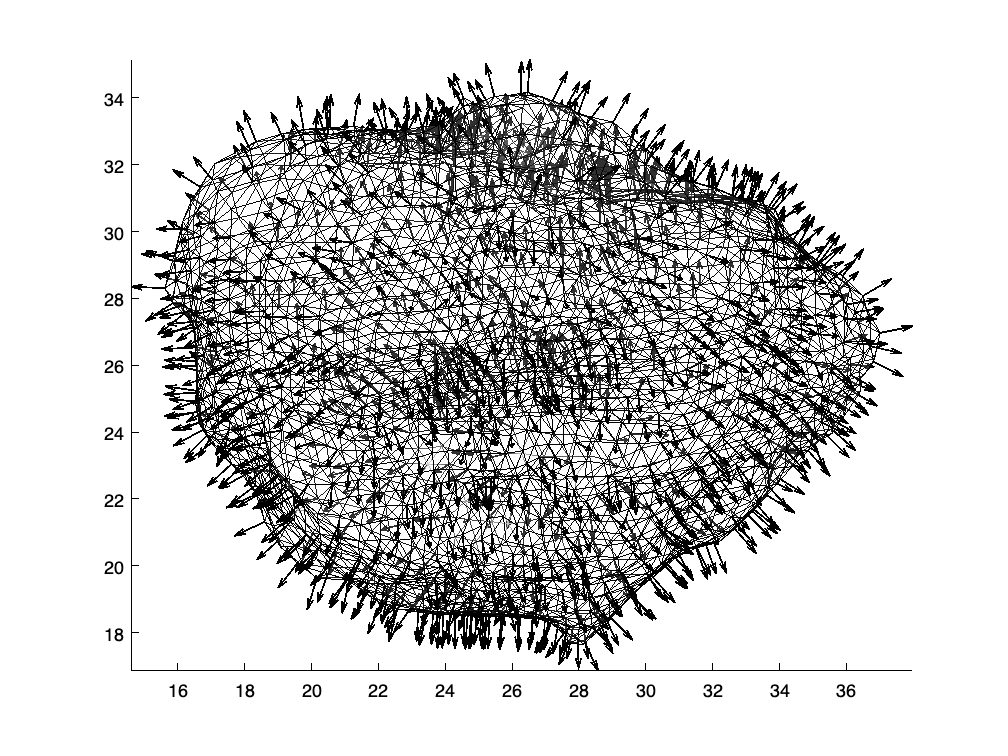

% None of the face normals are pointing inward. So we can use 'normals' in
% computing the surface normals at each vertex, which is the weighted
% average of neighboring face normals. 
% 
% Research note: The tangent plane at each vertex can be computed as the weighted average of each face.  

%Compute normal vectors at vertex
surfnormal =surf2normal(surf);

figure; figure_wire(surf,'k', 'w');
hold on; figure_quiver3D(surf.vertices, surfnormal, 2);

## Quadratic surface parameterization at vertex.

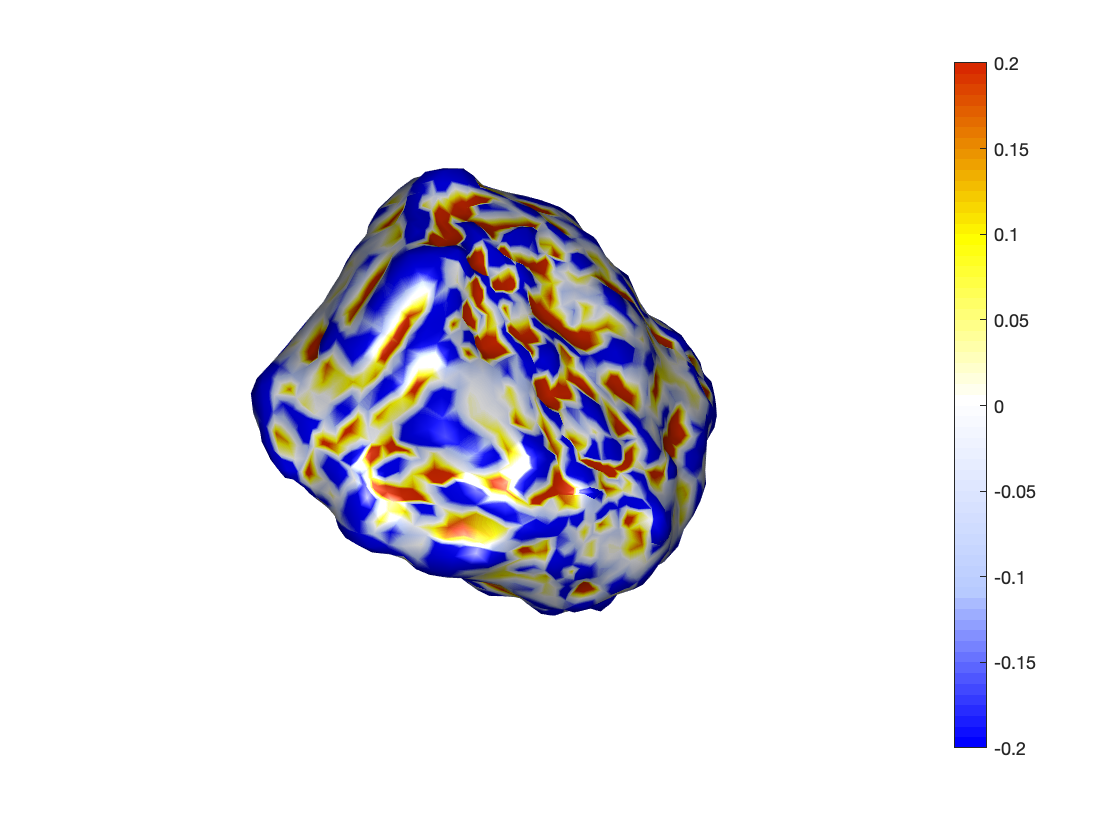

% Currently we are only using the first neighbors. If we increase up to the second neighbors, the performance will increase.
% The algorithm requires estimating the surface normals. Then the surface is rotated in such a way that the surface normal alines to z-axis.
% The algoirthm detail is given in 
%
% Chung. M.K. 2001, Statistical Morphometry in Computional Neuroanatomy, 
% PhD Thesis, McGill University, Montreal. 
% http://www.stat.wisc.edu/~mchung/papers/thesis.pdf

beta=surf2quadratic(surf);

%Research note: If you study inside the code, you will find out how to
%compute the surface normal at vertex. The tangent plane is simply the
%normal to the surface normal. The basis of the tangent plane can be
%identified from the quadratic surface parameterization. 

%Compute curvatures from the quadratic surfaces
curvatures=surf2curvature(beta);

%The mean curvature of amygdala
figure; figure_trimesh(surf, curvatures.mean, 'rwb'); caxis([-0.2 0.2]); 

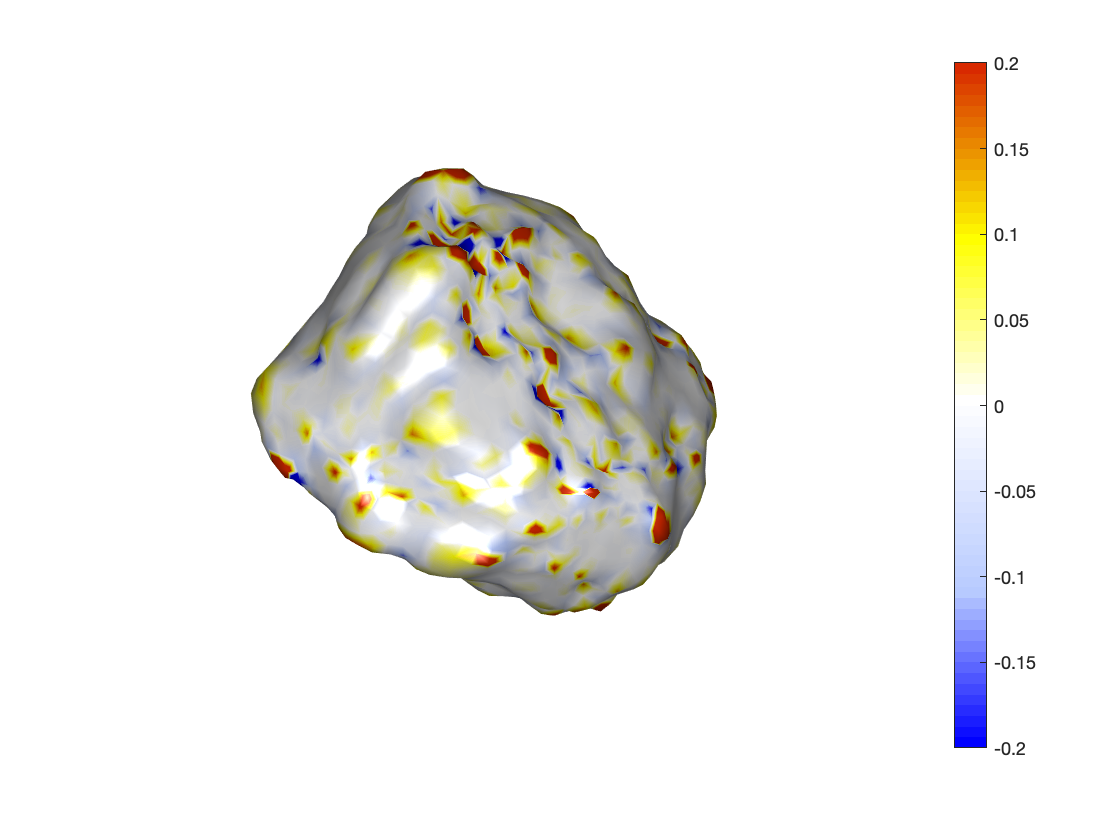

%Gaussian curvature of amygdala
figure; figure_trimesh(surf, curvatures.gaussian, 'rwb'); caxis([-0.2 0.2]); 

## Surface normals for brain cortical surface

% The computation is done on the white matter surface consisting of
%
%       faces: [331078×3 int32]
%    vertices: [165541×3 single]
%
%Load gifti surface file format
whiteL = gifti('130114.L.white.native.surf.gii'); 

%It will not be shown here but gray matter surface is also available
%grayL = gifti(130114.L.pial.native.surf.gii')


% The run time is 158-194 seconds in 2019 iMac
tic
normal =surf2normal(whiteL); %unit surface normal vector at vertex      
toc

Elapsed time is 194.146680 seconds.


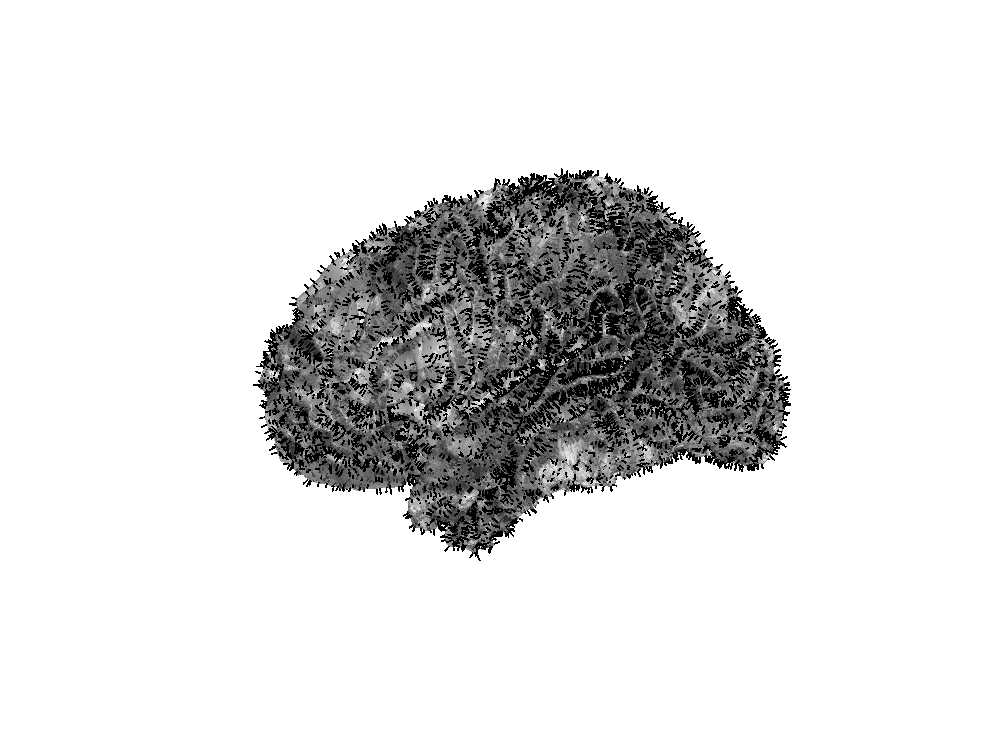

figure;  figure_patch(whiteL,[0.7 0.7 0.7], 0.5);
hold on; figure_quiver3D(whiteL.vertices, 2*normal, 10); 
view([-90 0])
figure_camlight

## Mean and Gassusian curvature for brain cortical surface

%The run time is 158-203 seconds in 2019 iMac

tic
beta=surf2quadratic(whiteL);
curvatures=surf2curvature(beta);
toc

Elapsed time is 202.929253 seconds.


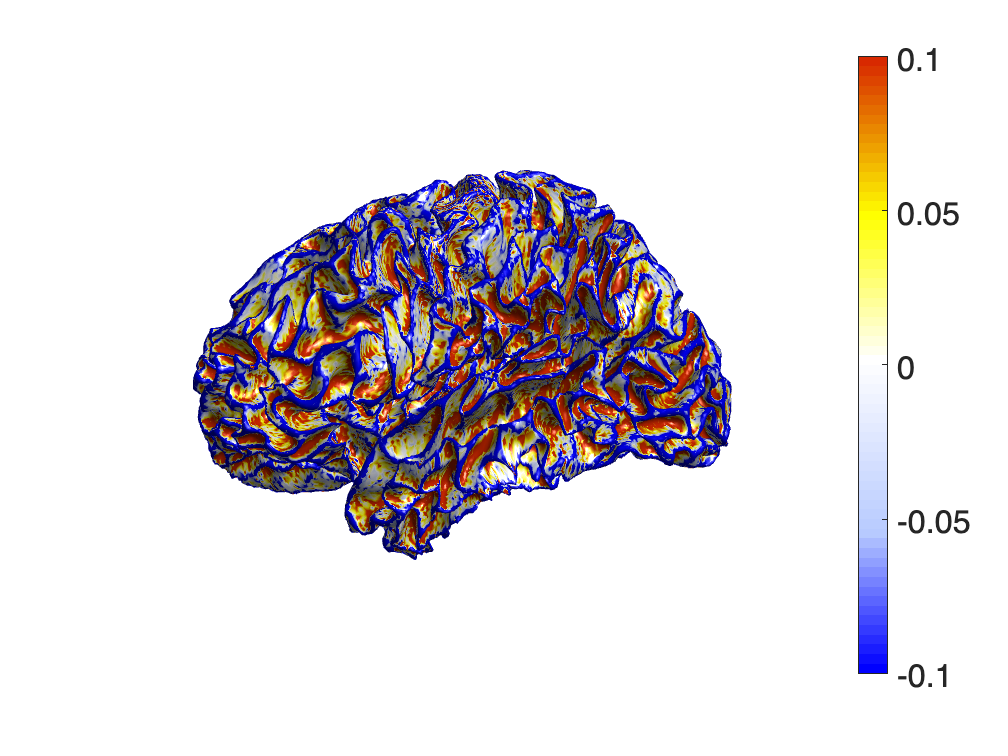

figure; figure_trimesh(whiteL, curvatures.mean, 'rwb'); caxis([-0.1 0.1]);view([-90 0])
figure_camlight

% Research note: We can perform the Holdge-Laplacian based heat kernel smoothing to the mean curvature. 
% Since every node is connected to 2 nodes, it has specific connectivity structure and computation can be done quickly. 